Total number of read CIR pairs for L1_R1_CIRs_Ch_9.txt: 223
Total number of read CIR pairs for L1_R2_CIRs_Ch_9.txt: 514
Total number of read CIR pairs for L1_R3_CIRs_Ch_9.txt: 517


CIR number 1 for L1_R1_CIRs_Ch_9.txt


Highest sample :739
Noise variance :0.00015246
Direct path :738


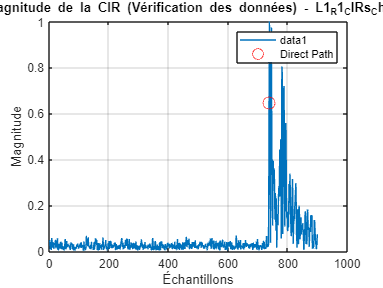

Distance estimée : 2.4 mètres


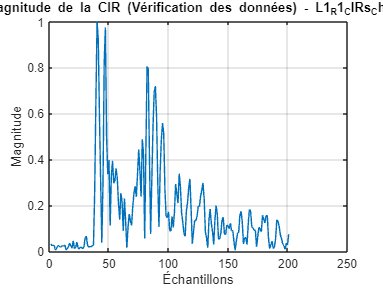

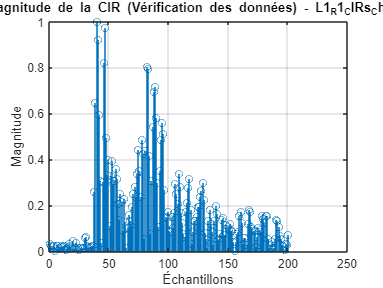

CIR number 1 for L1_R2_CIRs_Ch_9.txt


Highest sample :760
Noise variance :0.00045257
Direct path :739


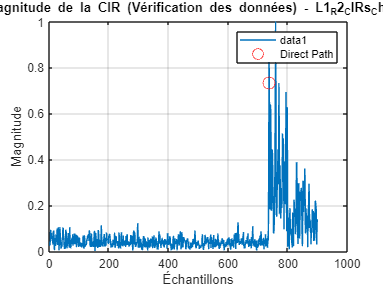

Distance estimée : 2.7 mètres


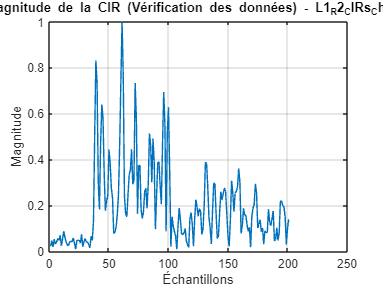

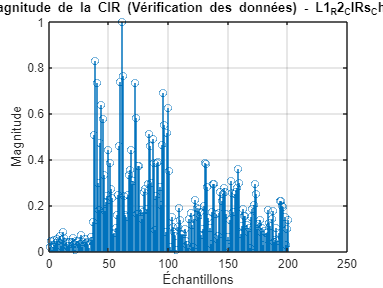

CIR number 1 for L1_R3_CIRs_Ch_9.txt


Highest sample :746
Noise variance :0.00024351
Direct path :746


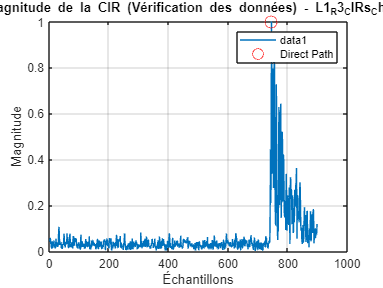

Distance estimée : 4.8 mètres


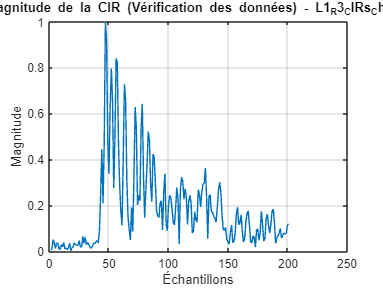

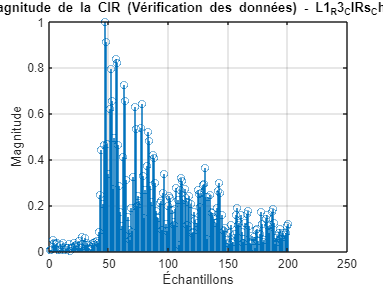

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ACTSlab - Sapienza Universita di Roma
% Author: 2024 Camille LANFREDI 

% Description : This MATLAB script reads and processes Channel Impulse
% Response (CIR) data from multiple specified files. It calculates the 
% magnitude of the CIR, identifies the direct path for both Line-of-Sight 
% (LOS) and Non-Line-of-Sight (NLOS) conditions, and visualizes various 
% aspects of the CIR data. The user is prompted to enter the CIR number
% to display and classify it as LOS or NLOS. The script then plots the 
% CIR magnitude, highlights the direct path, and calculates related parameters 
% such as estimated distances. Functions are included for detecting the first 
% path using variance methods for both LOS and NLOS conditions.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read files and extract data
file_paths = {'L1_R1_CIRs_Ch_9.txt', 'L1_R2_CIRs_Ch_9.txt', 'L1_R3_CIRs_Ch_9.txt'};

all_CIR_real_all = {};
all_CIR_imag_all = {};

for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurements(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end

while true
    % Prompt the user for the CIR number to display
    prompt = 'Enter the CIR number you want to display (1-1087) or 0 to exit: ';
    CIRNumber = input(prompt);
    
    if CIRNumber == 0 % To quit the bash press 0
        break;
    end

    for i = 1:length(file_paths)
        file_path = file_paths{i};
        CIR_real_all = all_CIR_real_all{i};
        CIR_imag_all = all_CIR_imag_all{i};

        if CIRNumber > 0 && CIRNumber <= length(CIR_real_all)
            disp(['CIR number ', num2str(CIRNumber), ' for ', file_path]);
            
            % Calculate CIR magnitude
            CIR_real = CIR_real_all{CIRNumber}';
            CIR_imag = CIR_imag_all{CIRNumber}';
            CIR_magnitude = sqrt(CIR_real.^2 + CIR_imag.^2);
            
            % Normalize the magnitude data
            CIR_magnitude = CIR_magnitude / max(CIR_magnitude);
            
            % Display CIR magnitude
            figure;
            plot(CIR_magnitude);
            title(['CIR Magnitude (Data Verification) - ', file_path]);
            xlabel('Samples');
            ylabel('Magnitude');
            grid on;
            
            % Prompt the user to classify as LOS or NLOS
            prompt = 'Enter the condition (LOS (1)/NLOS (0)) for the displayed CIR: ';
            condition = input(prompt, 's');
            
            % Detect the First Path based on the condition
            if strcmpi(condition, '1')
                directPathIdx = findFirstPathLOS(CIR_magnitude);
            elseif strcmpi(condition, '0')
                directPathIdx = findFirstPathNLOS(CIR_magnitude);
            else
                disp('Invalid condition entered.');
                continue;
            end
            % Annotate the First Path on the plot
            hold on;
            plot(directPathIdx, CIR_magnitude(directPathIdx), 'ro', 'MarkerSize', 10, 'DisplayName', 'Direct Path');
            legend('show');
            hold off;
            
            % Calculate the distance
            c = 3e8; % Speed of light (m/s)
            timePerSample = 1e-9; % Time per sample (in seconds)
            
            % Adjust the direct path index by subtracting the noise window
            noiseWindow = 725; % Size of the noise window
            adjustedDirectPathIdx = directPathIdx - noiseWindow;
            adjustedDirectPathIdx = max(adjustedDirectPathIdx, 0); % Ensure the index is non-negative
            
            % Calculate the time of flight
            timeDistance = adjustedDirectPathIdx * timePerSample;
            distance = timeDistance * c;

            % Display the result
            disp(['Estimated distance: ', num2str(distance), ' meters']);
        else
            disp(['Invalid CIR number for ', file_path]);
        end
        
        % Display CIR magnitude from sample 700 onwards
        figure;
        plot(CIR_magnitude(700:end));
        title(['CIR Magnitude (Data Verification) - ', file_path]);
        xlabel('Samples');
        ylabel('Magnitude');
        grid on;

        % Display CIR magnitude using stem plot from sample 700 onwards
        figure;
        stem(CIR_magnitude(700:end));
        title(['CIR Magnitude (Data Verification) - ', file_path]);
        xlabel('Samples');
        ylabel('Magnitude');
        grid on;
    end
end

% Function to detect the First Path for LOS condition
function directPathIdx = findFirstPathLOS(CIR_magnitude)
    % Detect the direct path using variance method for LOS
    noiseWindow = 730; % Initial window to estimate noise
    noiseVariance = var(CIR_magnitude(1:noiseWindow));
    thresholdFactor = 3.98; % Factor to detect significant variance increase
                            % Indicated in Segger code >
                            % dw3000_statistics.c > L188
    threshold = noiseVariance * thresholdFactor;
    [pks, locs] = findpeaks(CIR_magnitude);
    highestPeakIndex = locs(find(pks == max(pks), 1));
    disp(['Highest sample: ', num2str(highestPeakIndex)]);
    disp(['Noise variance: ', num2str(noiseVariance)]);
    % Iterate over samples after the noise window to detect variance increase
    directPathIdx = noiseWindow;
    for idx = (noiseWindow + 1):length(CIR_magnitude)
        if var(CIR_magnitude((idx-noiseWindow):idx)) > threshold
            directPathIdx = idx;
            break;
        end
    end
    disp(['Direct path: ', num2str(directPathIdx)]);
end

% Function to detect the First Path for NLOS
function directPathIdx = findFirstPathNLOS(CIR_magnitude)
    [pks, locs] = findpeaks(CIR_magnitude);
    highestPeakIndex = locs(find(pks == max(pks), 1));
    noiseWindow = 730; % Initial window to estimate noise
    noiseVariance = var(CIR_magnitude(1:noiseWindow));
    thresholdFactor = 3.98; % Factor to detect significant variance increase
                            % Indicated in Segger code >
                            % dw3000_statistics.c > L188
    threshold = noiseVariance * thresholdFactor;
    directPathIdx = highestPeakIndex; % Initialize with the highest peak index
    disp(['Highest sample: ', num2str(highestPeakIndex)]);
    disp(['Noise variance: ', num2str(noiseVariance)]);
    % Adjust based on variance
    for idx = (noiseWindow + 1):length(CIR_magnitude)
        if var(CIR_magnitude((idx-noiseWindow):idx)) > threshold
            directPathIdx = idx;
            break;
        end
    end
    disp(['Direct path: ', num2str(directPathIdx)]); 
end
